%% Visualization for the data:
clc, clearvars, close all
addpath('data/')
healthy = readmatrix("data/data.xlsx",'Sheet','No.2WT'); % Healthy turbine
WT3 = readmatrix("data/data.xlsx",'Sheet','No.3');
faulty14 = readmatrix("data/data.xlsx",'Sheet','No.14WT');
faulty39 = readmatrix("data/data.xlsx",'Sheet','No.39WT');



## Missing values

Checking the missing values and filling with the previous one


missing_2 = sum(isnan(healthy))

missing_2 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


missing_14 = sum(isnan(faulty14))

missing_14 =      0     0     0     0     0     0     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


ROWBYROW = 2;
faulty14 = fillmissing(faulty14,'previous',ROWBYROW);

missing_39 = sum(isnan(faulty39))

missing_39 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


WT3 data seems to not be in any consistent order compared to other datasets, and also has extra columns compared to them, so we are not using the data in this analysis. Dropping the last column from the healthy, because it is an extra quality variable and is not found from the remaining datasets.

healthy(:,end) = [];
labels = string(1:size(healthy, 2))

labels = 1×27 string array
    "1"    "2"    "3"    "4"    "5"    "6"    "7"    "8"    "9"    "10"    "11"    "12"    "13"    "14"    "15"    "16"    "17"    "18"    "19"    "20"    "21"    "22"    "23"    "24"    "25"    "26"    "27"


Removing the header row

healthy(1,:) = [];
faulty14(1,:) = [];
faulty39(1,:) = [];

% Normalized datas:
[norm_healthy, mu, sigma] = zscore(healthy)

norm_healthy =     1.1037   -1.3095    0.1974   -0.1397    0.0355    0.0238    0.0400    0.0515   -1.9389    0.0266    0.0619         0   -0.0454    0.4723         0   -1.4831    1.9825    0.3611    0.8302    0.4967    0.0484    1.6582   -1.6475    0.4175    1.9791   -0.7017   -0.5383
    0.3985   -0.4295    0.1974   -0.1103    0.0089    0.0316    0.0400    0.0489   -1.9338   -0.0011    0.0314         0   -0.0454   -0.7802         0   -1.4836    1.9825    0.5005    0.8302    0.4967   -0.0424    1.6582    0.4454   -0.0410    1.9791   -0.7017   -0.5498
    1.8090   -1.1628    0.1974   -0.1220    0.0013    0.0238    0.0400    0.0408   -1.9338   -0.0063    0.0134         0   -0.0454   -0.7802         0   -1.4836    1.9825    0.3611    0.8302    0.5860   -0.0424    1.6582   -0.0900    0.7723    1.9791   -0.7017   -0.5383
   -1.2472    0.8904    0.1974   -0.1103   -0.0337    0.0238    0.0592    0.0515   -1.9338   -0.0268   -0.0080         0   -0.0454    1.0985         0   -1.4831    1.9825  

mu = 1.0e+07 *

   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.3575    0.0000    0.0001    0.0002    0.0000   -0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


sigma =     0.0455    0.0739    1.4622    1.6317  117.1357    2.2889    2.2389    2.2330  397.9615  117.0907  146.6609         0    0.0144    1.5969         0   15.4066    1.4409    2.1488    0.0454    0.3024    0.2864    0.2197    4.6742    0.7837    2.5627    3.1453    1.9001


[norm_faulty14, mu14, sigma14] = zscore(faulty14(1:358,:)) % We will use datapoints before timestep 358 only:

norm_faulty14 =     4.4771   -0.0403    0.9407    1.0398   -0.0725    1.7454    1.7674    1.7627    0.0525   -0.0692    0.0170    0.0529   -0.2652   -0.0633    0.0529    0.2781    1.5741    0.0680    0.0214   -0.1292   -0.0875    0.4148   -0.8792    0.6325    1.8135    1.7294    2.2471
   -6.2158   -1.2905    0.9407    1.0370   -0.0725    1.7332    1.7490    1.7507    0.0525   -0.0692   -0.0593    0.0529    0.0535   -0.0633    0.0529    0.2781    1.5602    0.0846    0.0214   -0.1427   -0.0770    0.4148   -1.1433    1.4597    1.8135    1.6839    2.1535
    2.8732    1.2100    0.9407    1.0347   -0.0725    1.7205    1.7425    1.7379    0.0525   -0.0692   -0.0587    0.0529    0.0831   -0.0633    0.0529    0.2781    1.5602    0.0930    0.0177   -0.1292   -0.0858    0.4148   -1.2447    1.0953    1.8135    1.6359    2.0612
    2.3385   -1.9156    0.9407    1.0166   -0.0725    1.6984    1.7333    1.7255    0.0525   -0.0692   -0.0622    0.0529    0.0831   -0.0633    0.0529    0.2781    1.5602 

mu14 = 1.0e+07 *

   -0.0000   -0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    2.5915    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


sigma14 = 1.0e+06 *

    0.0000    0.0000    0.0000    0.0000    0.0001    0.0000    0.0000    0.0000    1.3735    0.0001    0.0009    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


norm_faulty39 = zscore(faulty39(1:470,:)) % We will use datapoints before timestep 471 only:

norm_faulty39 =     6.1257    0.3582    0.8810    1.1451   -0.9278    1.3039    1.2358    1.1316    0.0461         0    3.4204    0.0461   -0.4518    0.0460   -0.9494    0.1025   -1.8442    0.0142    0.0525    0.6663    0.6167    2.8915   -0.9321    0.9731   -0.5063    1.6471    2.2907
   -5.2298   -2.3390    0.8747    1.1451   -0.9278    1.2861    1.2358    1.1184    0.0461         0    1.2806    0.0461   -0.0137    0.0460   -0.9494    0.1025   -1.8442    0.0426    0.0438    0.6936    0.6167    2.8915    1.7450    0.7932   -0.5063    1.6020    2.2186
    1.9079   -0.4124    0.8810    1.1451   -0.9278    1.2661    1.2358    1.0918    0.0461         0   -0.1944    0.0461    0.0448    0.0460   -0.9494    0.1025   -1.8442    0.0710    0.0265    0.6880    0.6167    2.8915    1.1349   -0.0140   -0.5063    1.5569    2.1676
    2.8813    1.8995    0.8655    1.1451   -0.9278    1.2517    1.2358    1.0918    0.0461         0   -0.0444    0.0461    0.0476    0.0460   -0.9494    0.1025   -1.8442 


% Corresponding box plots:
boxplot(norm_healthy)

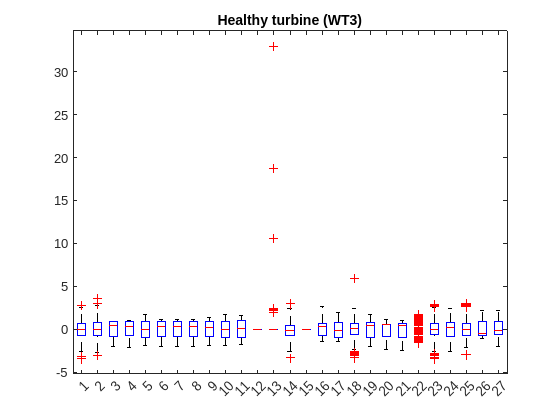

title('Healthy turbine (WT3)')

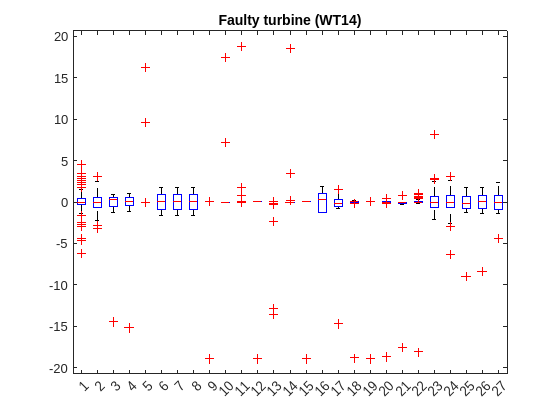

figure
boxplot(norm_faulty14)
title('Faulty turbine (WT14)')

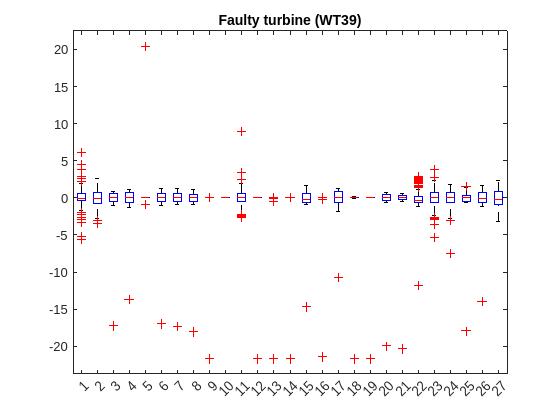

figure
boxplot(norm_faulty39)
title('Faulty turbine (WT39)')

### Data Summary

mean_2 = mean(healthy);
mean_14 = mean(healthy);
mean_39 = mean(healthy);

min_2 = min(healthy);
min_14 = min(faulty14);
min_39 = min(faulty39);

max_2 = max(healthy);
max_14 = max(faulty14);
max_39 = max(faulty39);

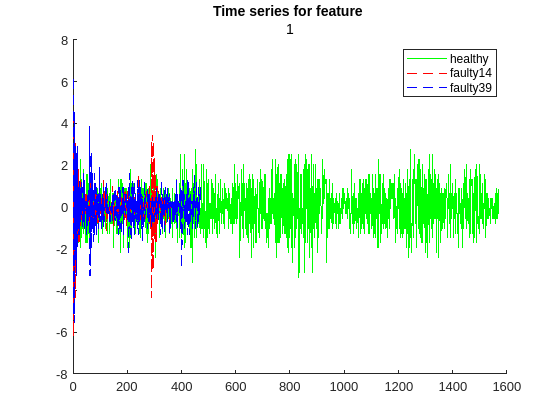

plotdata(norm_healthy,norm_faulty14,norm_faulty39,1)


plotdata(norm_healthy,norm_faulty14,norm_faulty39,2)


plotdata(norm_healthy,norm_faulty14,norm_faulty39,3)

## Data splitting

Splitting the data into calibration, validation and test sets

CALIBRATION_SIZE = 0.7;
VALIDATION_SIZE = 0.2;
TEST_SIZE = 0.1;

n_healthy_calib = floor(size(norm_healthy,1)*CALIBRATION_SIZE);
n_healthy_valid = floor(size(norm_healthy,1)*VALIDATION_SIZE);
n_healthy_test = size(norm_healthy,1) - (n_healthy_calib + n_healthy_valid);

norm_healthy_calib = norm_healthy(1:n_healthy_calib,:);
norm_healthy_valid = norm_healthy(n_healthy_calib+1:n_healthy_calib + n_healthy_valid,:);
norm_healthy_test = norm_healthy(end-n_healthy_test:end,:);

## Correlation plot

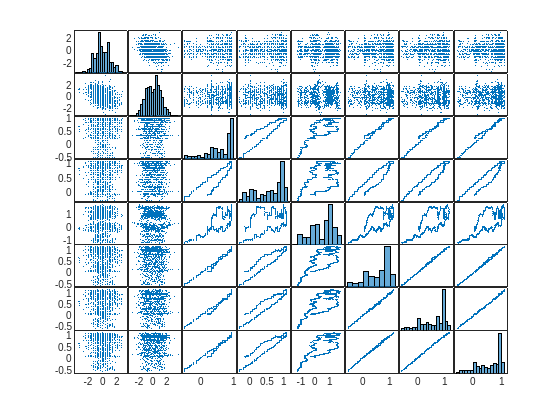

figure
gplotmatrix(norm_healthy_calib(:,1:8), [])

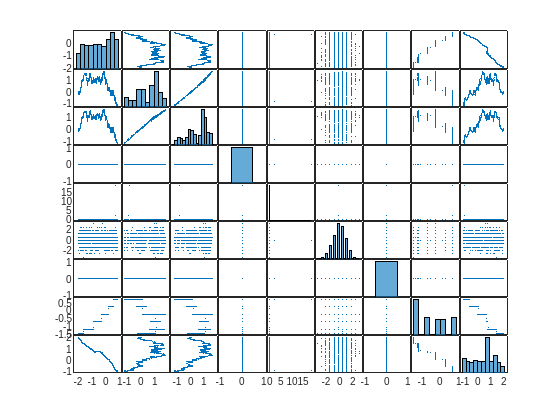

figure
gplotmatrix(norm_healthy_calib(:,9:17), [])

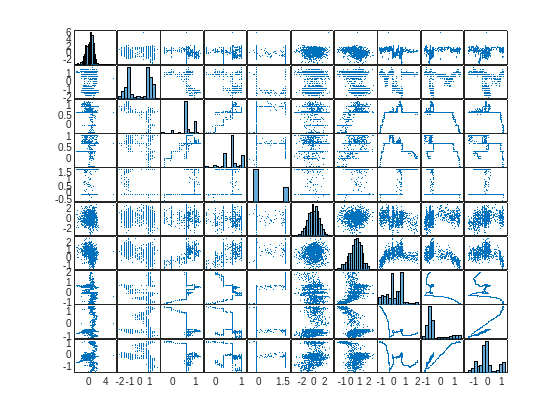

figure
gplotmatrix(norm_healthy_calib(:,18:27), [])

## PCA


model(1).X = norm_healthy_calib; %Pretreat data
[model(1).P, model(1).T, model(1).latent, model(1).T2all, model(1).explVar, model(1).mu] = pca(model(1).X);



model(2).X = norm_faulty14; %Pretreat data
[model(2).P, model(2).T, model(2).latent, model(2).T2all, model(2).explVar, model(2).mu] = pca(model(2).X);



model(3).X = norm_faulty39; %Pretreat data
[model(3).P, model(3).T, model(3).latent, model(3).T2all, model(3).explVar, model(3).mu] = pca(model(3).X);

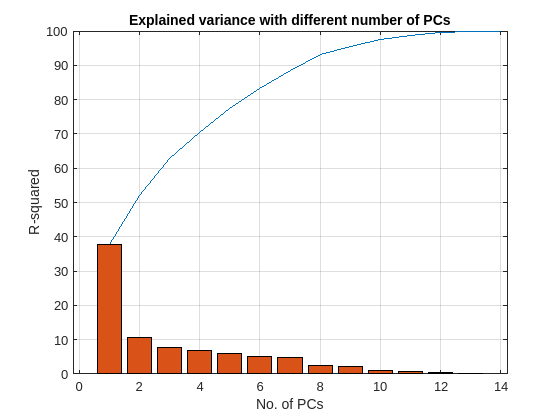

figure; 
explVar = 100 * cumsum(model(1).latent(1:14)) / sum(model(1).latent(1:14));
changeAmount(1) = explVar(1);
for i = 2:length(explVar)-1
    changeAmount(i) = explVar(i+1)-explVar(i);
end
plot(1:14, explVar); hold on;
bar(changeAmount)
title('Explained variance with different number of PCs'); 
xlabel("No. of PCs"); ylabel("R-squared"); grid on;

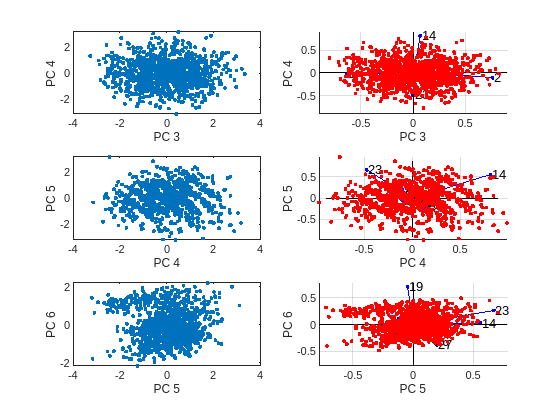

figure; 
ii = 1;

for i = 3:5

    subplot(3,2,ii);
    gscatter(model(1).T(:,i), model(1).T(:,i+1));
    text1 = "PC " + string(i);
    text2 = "PC " + string(i+1);
    xlabel(text1);
    ylabel(text2);
    ii      = ii + 1;

    subplot(3, 2, ii);
    biplot(model(1).P(:,i:(i+1)), 'Scores', model(1).T(:,i:(i+1)), 'VarLabels', labels);
    xlabel(text1);
    ylabel(text2);
    ii = ii + 1;
end

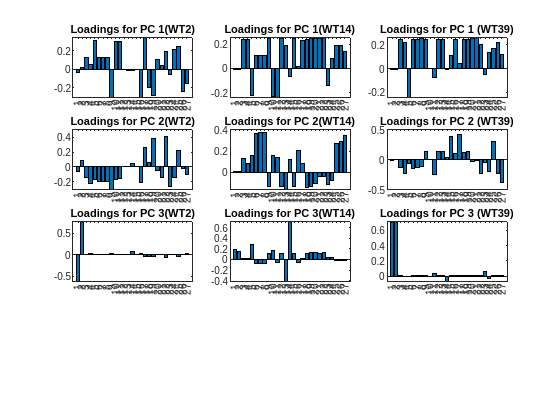

%% Loadings
figure;
ii = 1;
for i = 1:3
    subplot(4,3,ii);
    bar(1:27,model(1).P(:,i)); %Loadings bar plot
    text = "Loadings for PC " + string(i) + "(WT2)";
    title(text);
    xticks(1:27)

    subplot(4,3,ii+1);
    bar(1:27,model(2).P(:,i)'); %Loadings bar plot
    text = "Loadings for PC " + string(i) + "(WT14)";
    title(text);
    xticks(1:27)

    subplot(4,3,ii+2);
    bar(1:27,model(3).P(:,i)'); %Loadings bar plot
    text = "Loadings for PC " + string(i) + " (WT39)";
    title(text);
    xticks(1:27)
    ii = ii + 3;
end

## Finding the features from WT14 and WT39 where loadings differ most from WT2:

% Calculating the absolute differences between WT2 vs WT14 & WT39
for i = 1:1:8
    diff14(:,i) = abs(abs(model(1).P(:,i))-abs(model(2).P(:,i)));
    diff39(:,i) = abs(abs(model(1).P(:,i))-abs(model(3).P(:,i)));
end
% And finding the top three indices for each principal component:
indeces14 = [];
indeces39 = [];
for i = 1:1:8
    [maxval maxind] = maxk(diff14(:,i),3);
    indeces14(:,i) = maxind;


    [maxval maxind] = maxk(diff39(:,i),3);
    indeces39(:,i) = maxind;

end

%Found top 3 features (rows) for each component (columns).
indeces14

indeces14 =     16    22    14    14     1    19    18    23
    12    19     2    24     2     2    24     1
    15    26     1    16    23     1    16     2


indeces39

indeces39 =     10    15     1    14    14    11    18    24
    17    27    22    23    23    19     1     1
    12    19    23    24    18     2     2     2


% Calculating the amount of instances where each feature appears in top 3
% differing

[counts, ~] = histcounts(indeces14,'BinMethod','integers')

counts =      4     4     0     0     0     0     0     0     0     0     0     1     0     2     1     3     0     1     2     0     0     1     2     2     0     1


[counts2, ~] = histcounts(indeces39,'BinMethod','integers')

counts2 =      3     3     0     0     0     0     0     0     0     1     1     1     0     2     1     0     1     2     2     0     0     1     3     2     0     0     1


counts(end+1) = 0

counts =      4     4     0     0     0     0     0     0     0     0     0     1     0     2     1     3     0     1     2     0     0     1     2     2     0     1     0


total_count = counts+counts2

total_count =      7     7     0     0     0     0     0     0     0     1     1     2     0     4     2     3     1     3     4     0     0     2     5     4     0     1     1


[maxvalues, maxindeces] = maxk(total_count,3)

maxvalues =      7     7     5


maxindeces =      1     2    23


## Datasets for PLS

The chosen sensors for the modelling are 5 and 9

y_1_idx = 5;

y_1_calib = norm_healthy_calib(:,y_1_idx);
y_1_test = norm_healthy_test(:,y_1_idx);
y_1_valid = norm_healthy_valid(:,y_1_idx);

X_1_calib = norm_healthy_calib(:,[1:y_1_idx-1, y_1_idx+1:end]);
X_1_test = norm_healthy_test(:,[1:y_1_idx-1, y_1_idx+1:end]);
X_1_valid_optim = norm_healthy_valid(:,[1:y_1_idx-1, y_1_idx+1:end]);

## PLS Models

[Xl, yl, XS, YS, beta, PCTVAR, MSE, stats] = plsregress(X_1_calib, ...
                                                        y_1_calib, ...
                                                        9, ...
                                                        'cv', 5);


## Testing

pls_labels_1 = string([0:y_1_idx-1, y_1_idx+1:length(beta)])

pls_labels_1 = 1×27 string array
    "0"    "1"    "2"    "3"    "4"    "6"    "7"    "8"    "9"    "10"    "11"    "12"    "13"    "14"    "15"    "16"    "17"    "18"    "19"    "20"    "21"    "22"    "23"    "24"    "25"    "26"    "27"


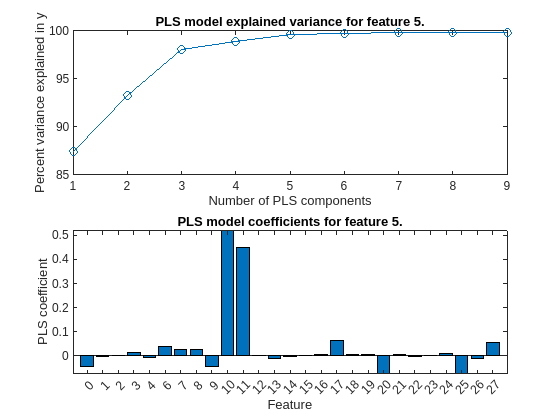


figure
subplot(2,1,1)
plot(1:9, cumsum(100*PCTVAR(2,:)), '-o')
xlabel('Number of PLS components')
ylabel('Percent variance explained in y')
title('PLS model explained variance for feature 5.')

subplot(2,1,2)
bar(pls_labels_1, beta)
xlabel('Feature')
ylabel('PLS coefficient')
title('PLS model coefficients for feature 5.')

axis tight

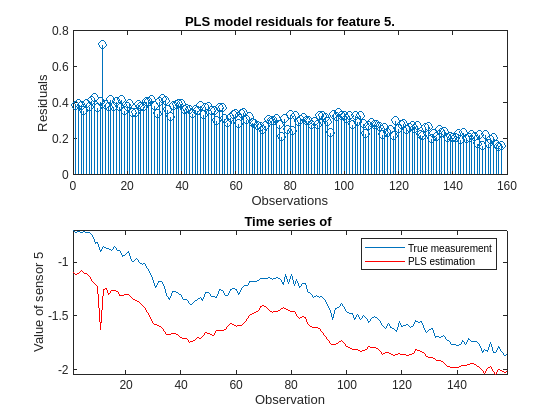

figure

yfit = [ones(size(X_1_test,1),1) X_1_test]*beta;
residuals = y_1_test - yfit;

subplot(2,1,1)
stem(residuals)
xlabel('Observations');
ylabel('Residuals');
title('PLS model residuals for feature 5.')

subplot(2,1,2)
plot(y_1_test)
hold on
plot(yfit, 'r')
hold off
legend('True measurement', 'PLS estimation')
xlabel('Observation')
ylabel('Value of sensor 5')
title('Time series of ')

axis tight

## Choosing variables

% Lets choose variables 10, 11, 20 and 25 and 3 pls components

used_vars_1 = [10, 11, 20, 25];

X_1_calib_optim = norm_healthy_calib(:,used_vars_1);
X_1_test_optim = norm_healthy_test(:,used_vars_1);
X_1_valid_optim = norm_healthy_valid(:,used_vars_1);


## New PLS

[Xl, yl, XS, YS, beta_1, PCTVAR, MSE, stats] = plsregress(X_1_calib_optim, ...
                                                        y_1_calib, ...
                                                        3, ...
                                                        'cv', 5);

## Prediction

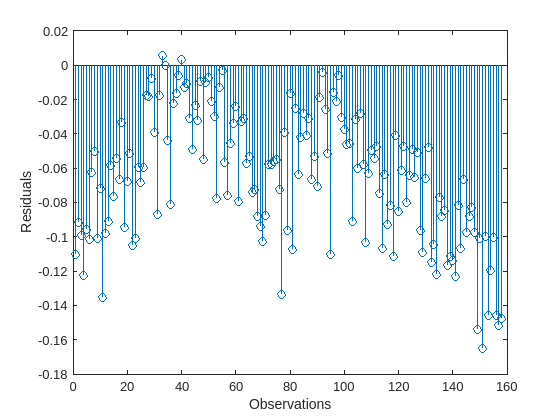

yfit = [ones(size(X_1_test_optim,1),1) X_1_test_optim]*beta_1;
residuals = y_1_test - yfit;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

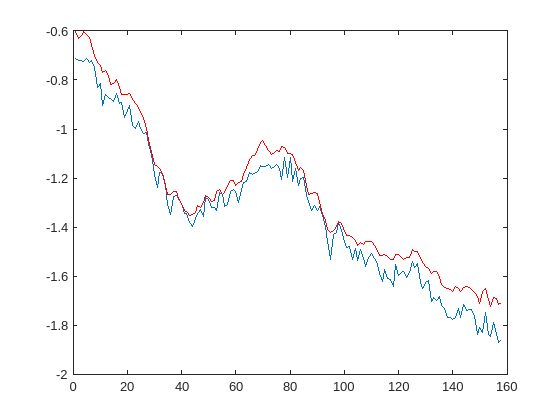

figure
plot(y_1_test)
hold on
plot(yfit, 'r')

## PLS for variable 9

y_2_idx = 9

y_2_idx = 9


y_2_calib = norm_healthy_calib(:,y_2_idx);
y_2_test = norm_healthy_test(:,y_2_idx);
y_2_valid = norm_healthy_valid(:,y_2_idx);

X_2_calib = norm_healthy_calib(:,[1:y_2_idx-1, y_2_idx+1:end]);
X_2_test = norm_healthy_test(:,[1:y_2_idx-1, y_2_idx+1:end]);
X_2_valid_optim = norm_healthy_valid(:,[1:y_2_idx-1, y_2_idx+1:end]);

## PLS

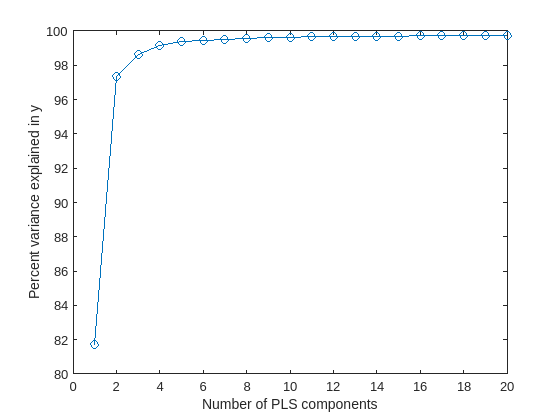

[Xl, yl, XS, YS, beta, PCTVAR, MSE, stats] = plsregress(X_2_calib, ...
                                                        y_2_calib, ...
                                                        20, ...
                                                        'cv', 5);

figure
plot(1:20, cumsum(100*PCTVAR(2,:)), '-o')
xlabel('Number of PLS components')
ylabel('Percent variance explained in y')

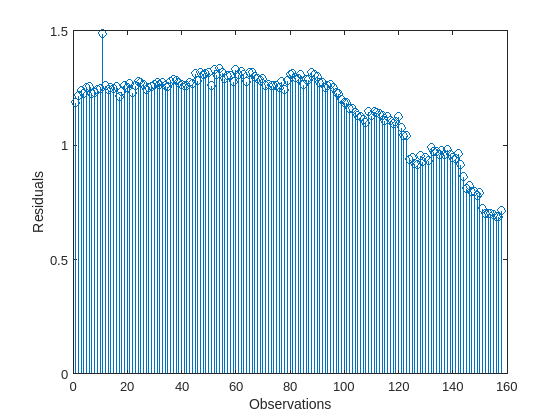

yfit = [ones(size(X_2_test,1),1) X_2_test]*beta;
residuals = y_2_test - yfit;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

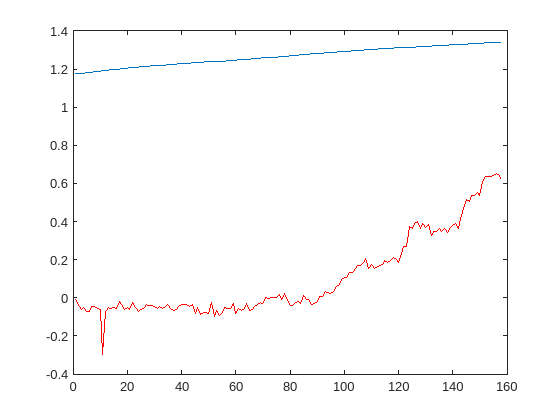


figure
plot(y_2_test)
hold on
plot(yfit, 'r')


pls_labels_2 = string([0:y_2_idx-1, y_2_idx+1:length(beta)])

pls_labels_2 = 1×27 string array
    "0"    "1"    "2"    "3"    "4"    "5"    "6"    "7"    "8"    "10"    "11"    "12"    "13"    "14"    "15"    "16"    "17"    "18"    "19"    "20"    "21"    "22"    "23"    "24"    "25"    "26"    "27"


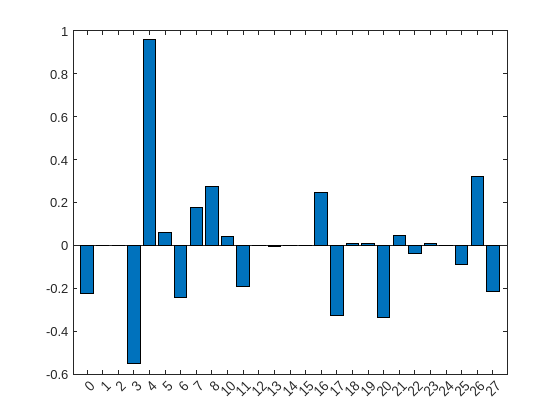

figure
bar(pls_labels_2, beta)

## Choosing the variables for the sensor 9 model

We choose variables 16, 17, 20 and 25 and 2 PLS components

used_vars_2 = [3, 4, 17, 20];

X_2_calib_optim = norm_healthy_calib(:,used_vars_2);
X_2_test_optim = norm_healthy_test(:,used_vars_2);
X_2_valid_optim = norm_healthy_valid(:,used_vars_2);


## Optimal PLS for 9

[Xl, yl, XS, YS, beta_2, PCTVAR, MSE, stats] = plsregress(X_2_calib_optim, ...
                                                        y_2_calib, ...
                                                        3, ...
                                                        'cv', 5);


## Testing

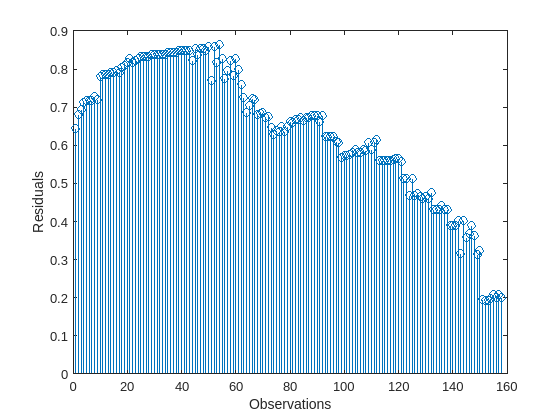

yfit = [ones(size(X_2_test_optim,1),1) X_2_test_optim]*beta_2;
residuals = y_2_test - yfit;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

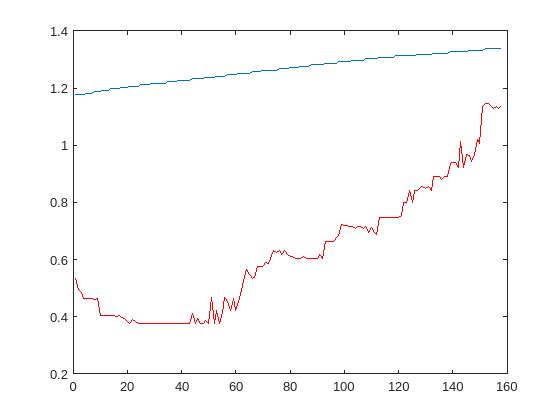

figure
plot(y_2_test)
hold on
plot(yfit, 'r')

## Testing on a faulty turbine

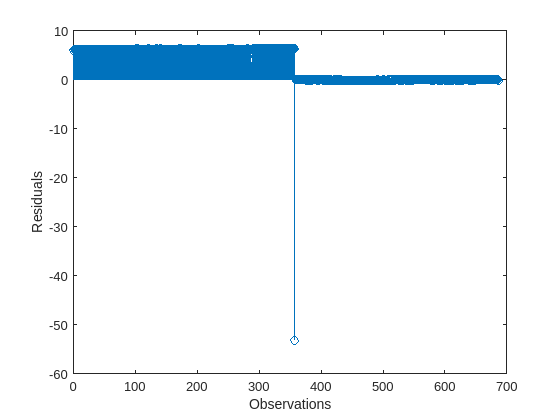

faulty14_normalized = (faulty14 - mu) ./ sigma;
faulty39_normalized = (faulty39 - mu) ./ sigma;

faulty14_sensor_1_X = faulty14_normalized(:,used_vars_1);
faulty14_sensor_1_y = faulty14_normalized(:,y_1_idx);

yfit_faulty14 = [ones(size(faulty14_sensor_1_X,1),1), faulty14_sensor_1_X]*beta_1;
residuals = faulty14_sensor_1_y - yfit_faulty14;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

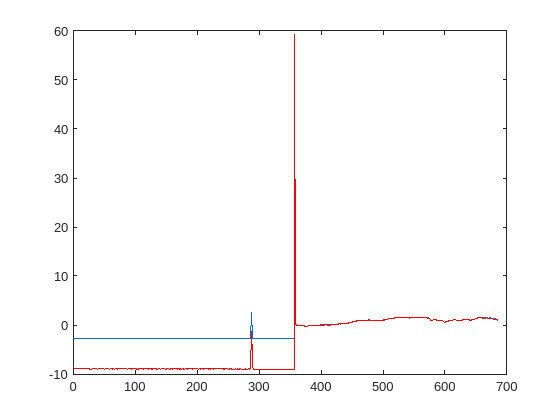

figure
plot(faulty14_sensor_1_y)
hold on
plot(yfit_faulty14, 'r')

## WT39

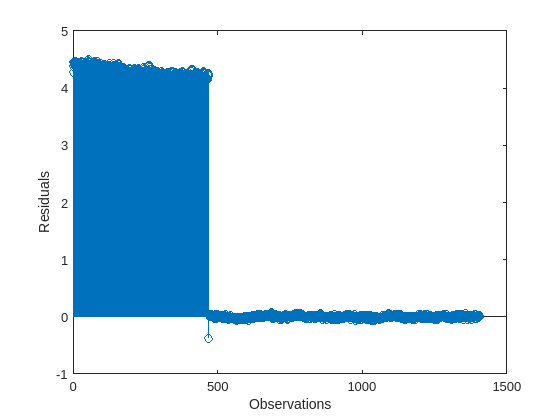

faulty39_sensor_1_X = faulty39_normalized(:,used_vars_1);
faulty39_sensor_1_y = faulty39_normalized(:,y_1_idx);

yfit_faulty39 = [ones(size(faulty39_sensor_1_X,1),1), faulty39_sensor_1_X]*beta_1;
residuals = faulty39_sensor_1_y - yfit_faulty39;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

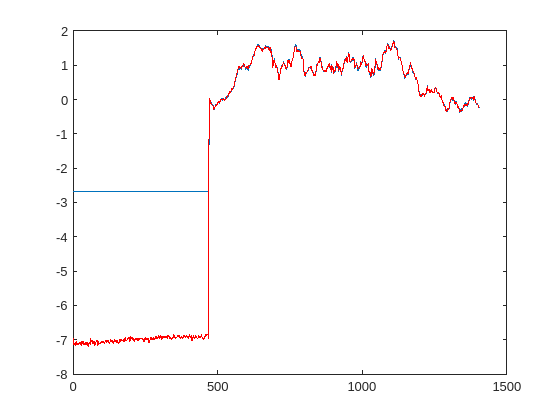


figure
plot(faulty39_sensor_1_y)
hold on
plot(yfit_faulty39, 'r')

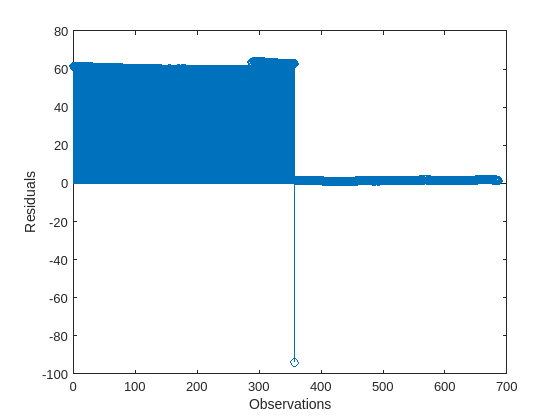


yfit_faulty14 = [ones(size(faulty14_sensor_1_X,1),1), faulty14_sensor_1_X]*beta_2;
residuals = faulty14_sensor_1_y - yfit_faulty14;
figure
stem(residuals)
xlabel('Observations');
ylabel('Residuals');

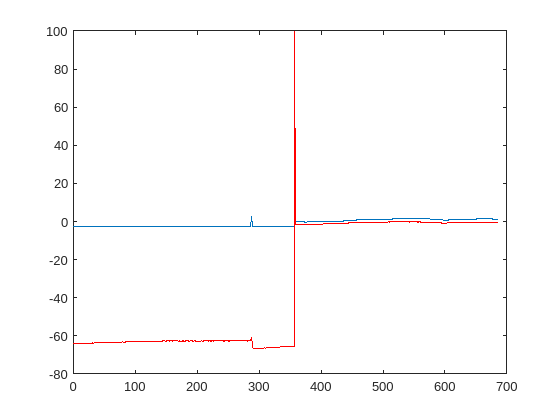

figure
plot(faulty14_sensor_1_y)
hold on
plot(yfit_faulty14, 'r')

function [H] = plotdata(healthy,faulty14,faulty39,column)
    figure
    hold on
    plot(healthy(:,column),'g-')
    plot(faulty14(:,column),'r--')
    plot(faulty39(:,column),'b--')
    title('Time series for feature ',column)
    legend('healthy','faulty14','faulty39')
end
